% Compute corner detection with MATLAB, 
% and compare with the outcome of problem (2).

% read corner patch (5*5)
corner_patch = imread('./images/corner_patch.jpg');

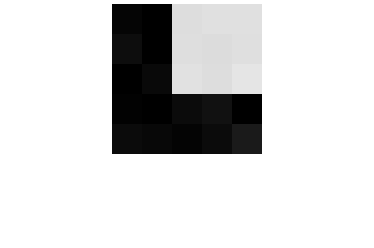

% visualize edge patch
figure; 
imshow(corner_patch, 'InitialMagnification', 3000);
title('corner patch')

% corner detection
corners = detectHarrisFeatures(corner_patch, "FilterSize", 3)

corners =   cornerPoints with properties:

    Location: [2.9773 3.0150]
      Metric: 0.0939
       Count: 1


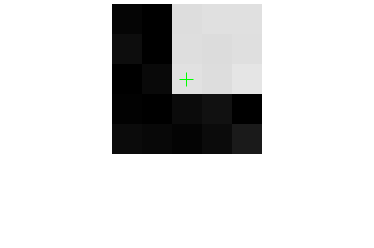

% visualize corner
imshow(corner_patch, 'InitialMagnification', 3000);
hold on;
plot(corners.selectStrongest(2))
title('Corner detected')